# Creating Maps From Arrays

Copyright 2021, The MathWorks, Inc

This script shows how to create Occupancy maps for autonomous navigation using data already available in MATLAB®. For more information please visit the following documentation:

- [Occupancy Grids](https://www.mathworks.com/help/nav/ug/occupancy-grids.html)

- [binaryOccupancyMap](https://www.mathworks.com/help/robotics/ref/binaryoccupancymap.html)

- [occupancyMap](https://www.mathworks.com/help/nav/ref/occupancymap.html)

- [occupancyMap3D](https://www.mathworks.com/help/nav/ref/occupancymap3d.html)

### Create Occupancy Map Object

Create a map of 10 meters by 10 meters with a resolution 5 cells per meter

myMap = binaryOccupancyMap(10,10,5)

myMap =   binaryOccupancyMap with properties:

   mapLayer Properties
              LayerName: 'binaryLayer'
               DataType: 'logical'
           DefaultValue: 0
    GridLocationInWorld: [0 0]
      GridOriginInLocal: [0 0]
     LocalOriginInWorld: [0 0]
             Resolution: 5
               GridSize: [50 50]
           XLocalLimits: [0 10]
           YLocalLimits: [0 10]
           XWorldLimits: [0 10]
           YWorldLimits: [0 10]


### Create Numeric Array with Matching Size

walls = zeros(50,50);
walls(1,:) = 1; % Top wall
walls(end,:) = 1; % Bottom wall
walls(:,1) = 1; % Left wall
walls(:,end) = 1; % Right wall
walls(1:30,15) = 1; % Left division
walls(25:end,25) = 1; % Middle division
walls(1:30,35) = 1 % Right division

walls =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     

### Assign Array to Occupancy Values

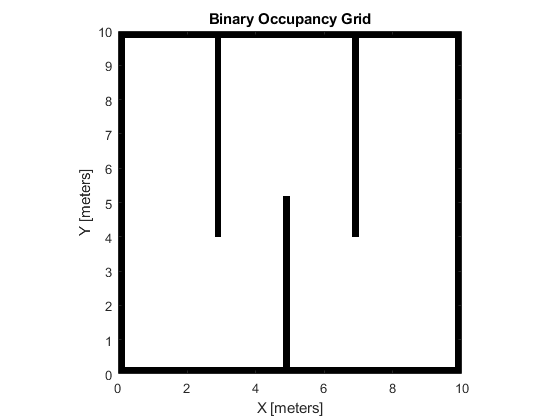

 
setOccupancy(myMap,[1 1],walls,"grid")
show(myMap)

### Inflate Map to Account for Robot Size

inflateRadius =0.3

inflateRadius = 0.3000

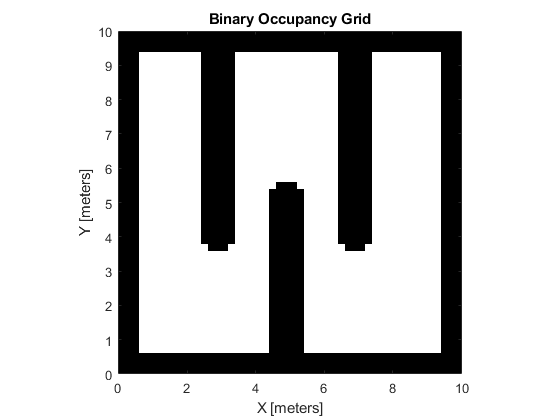

inflate(myMap,inflateRadius)
show(myMap)

### Check Occupancy In World Coordinates (meters)

Occupied = checkOccupancy(myMap,[5 5])

Occupied = 1

### Create a 3D Occupancy Map

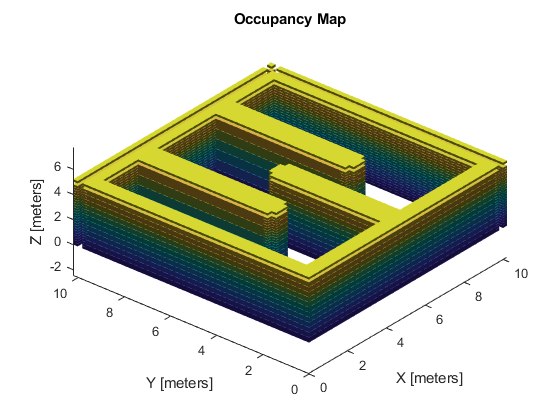

my3DMap = occupancyMap3D(5);
x = linspace(0,10,50)';
y = linspace(0,10,50)';
z = linspace(0,5,25);

% Arrange coordinates in XYZ format with increasing height
mapXY = [repelem(x,50) repmat(y,50,1)];
mapXYZ=[repmat(mapXY,25,1) repelem(z,2500)'];

% Get occupied space from 2D map and extrude in Z
occ3D = checkOccupancy(myMap,mapXY);
occ3D = repmat(occ3D,25,1);

% Set occupied space in the map
setOccupancy(my3DMap, mapXYZ, occ3D);

% Create map visualization
show(my3DMap)

### Visualize 3D Map used for UAV Navigation

If you have access to the [UAV Toolbox](https://www.mathworks.com/products/uav.html), you can also explore the map contained as part of the example:[ Motion Planning for Fixed Wing UAV.](matlab: openExample('uav/MotionPlanningWithRRTForAFixedWingUAVExample'))

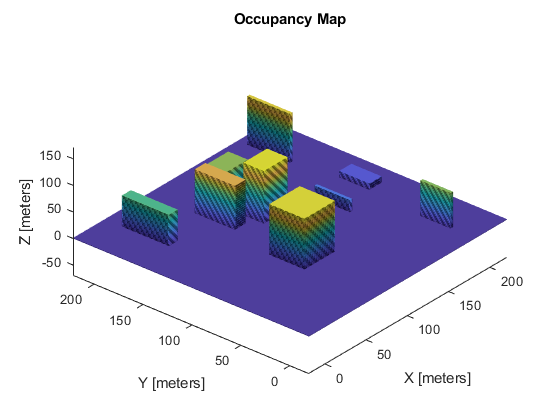

mapData = load("uavMapCityBlock.mat");
show(mapData.omap)